load sampleEEGdata.mat

### The following code calculates the TF plot for all the electrodes in the theta, alpha and beta bands

This code initially performs FFT for every single trial, creating TF data of dimensions: no_of_frequency_analyzed_per_band x no_of_data_points x no_of_bands x no_of_electrodes x no_of_trials

ndiv = 24;

freq_band1 = linspace(4,8,ndiv);
freq_band2 = linspace(8,12,ndiv);
freq_band3 = linspace(12,35,ndiv);


time = -1:1/EEG.srate:1;
hf_wv_size = (length(time) - 1)/2;

e = 37;
signal = EEG.data(:,:,:);

n_signal = length(signal);
n_wavelet= length(time);
n_conv = n_signal + n_wavelet - 1;
n_conv_pow2 = pow2(nextpow2(n_conv)); %Optimizing FFT

fft_s = fft(signal, n_conv_pow2,2);
tf_mat = zeros(ndiv,EEG.pnts,3,EEG.nbchan,EEG.trials);

for fi = 1:length(freq_band1)
    s = 6/(2*pi*freq_band1(fi));
    m_wvlet = exp(2*pi*1i*freq_band1(fi).*time).*exp((-time.^2)./(2*s^2));
    fft_w = fft(m_wvlet, n_conv_pow2);

    conv_signal = fft_w.*fft_s;
    ifft_s = ifft(conv_signal, n_conv_pow2,2);
    ifft_s = ifft_s(:,1:n_conv,:);
    ifft_s = ifft_s(:,hf_wv_size + 1: end - hf_wv_size,:);
    tf_mat(fi,:,1,:,:) = permute(ifft_s,[2 1 3]);
end

for fi = 1:length(freq_band2)
    s = 6/(2*pi*freq_band2(fi));
    m_wvlet = exp(2*pi*1i*freq_band2(fi).*time).*exp((-time.^2)./(2*s^2));
    fft_w = fft(m_wvlet, n_conv_pow2);

    conv_signal = fft_w.*fft_s;
    ifft_s = ifft(conv_signal, n_conv_pow2,2);
    ifft_s = ifft_s(:,1:n_conv,:);
    ifft_s = ifft_s(:,hf_wv_size + 1: end - hf_wv_size,:);
    tf_mat(fi,:,2,:,:) = permute(ifft_s,[2 1 3]);
end

for fi = 1:length(freq_band3)
    s = 6/(2*pi*freq_band3(fi));
    m_wvlet = exp(2*pi*1i*freq_band3(fi).*time).*exp((-time.^2)./(2*s^2));
    fft_w = fft(m_wvlet, n_conv_pow2);

    conv_signal = fft_w.*fft_s;
    ifft_s = ifft(conv_signal, n_conv_pow2,2);
    ifft_s = ifft_s(:,1:n_conv,:);
    ifft_s = ifft_s(:,hf_wv_size + 1: end - hf_wv_size,:);
    tf_mat(fi,:,3,:,:) = permute(ifft_s,[2 1 3]);
end

tf_pow = abs(tf_mat).^2;

The following code will now take the mean of the FFT data and plot the TF data

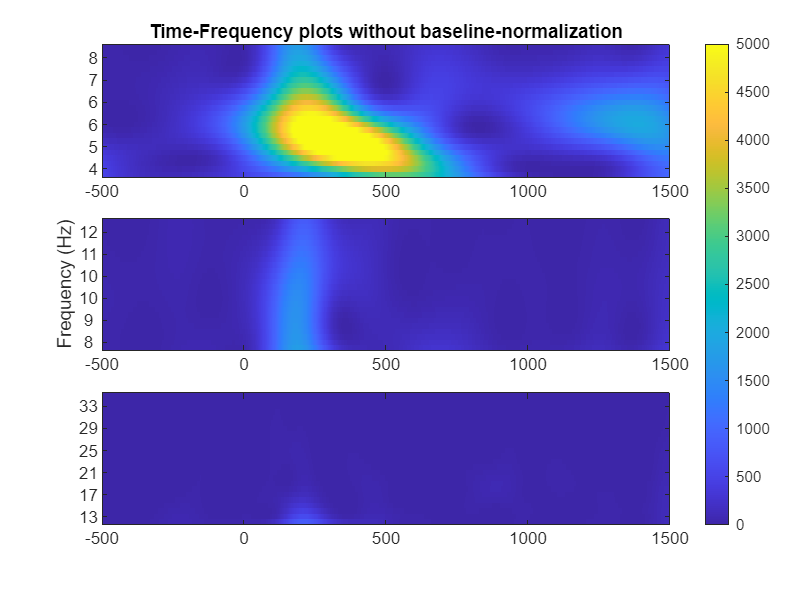

tf_mean = mean(tf_mat,5);
tf_mean_pow =abs(tf_mean).^2;

figure;
ytickskip = 2:4:ndiv;
tiledlayout(3,1)

%TF plot for theta band without baseline normalization
nexttile()
imagesc(EEG.times, [], tf_mean_pow(:,:,1,e))
title("Time-Frequency plots without baseline-normalization")
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band1(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])

%TF plot for alpha band without baseline normalization
nexttile()
imagesc(EEG.times, [], tf_mean_pow(:,:,2,e))
ylabel("Frequency (Hz)")
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band2(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])

%TF plot for beta band without baseline normalization
nexttile()
imagesc(EEG.times, [], tf_mean_pow(:,:,3,e))
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band3(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])

cb = colorbar();
cb.Layout.Tile = 'east';

### The following codes applies baseline normalization and converts the TF data into decibel reading betweem -12dB to +12dB

The following code applies baseline normalization to the mean of the TF power data obtained earlier

tf_dB = zeros(ndiv,EEG.pnts,3, EEG.nbchan);

baselinetime = [-400 -100]; % in ms

[~, baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~, baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

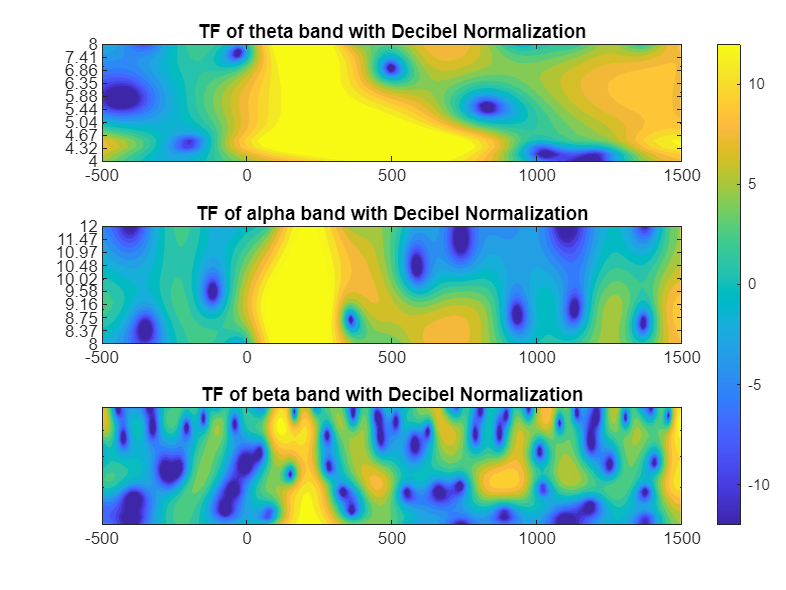

baseline_power = mean(tf_mean_pow(:,baselineidx(1):baselineidx(2),:,:),2);

for band = 1:3
    tf_dB(:,:,band,:) = 10*log10(bsxfun(@rdivide, tf_mean_pow(:,:,band,:), baseline_power(:,:,band,:)));
end

figure;
ytickskip = 2:4:ndiv;
tiledlayout(3,1)

%TF plot for theta band with baseline normalization

nexttile()
contourf(EEG.times,freq_band1, tf_dB(:,:,1,e),40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(freq_band1(1)),log10(freq_band1(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
title('TF of theta band with Decibel Normalization')

%TF plot for alpha band with baseline normalization
nexttile()
contourf(EEG.times,freq_band2, tf_dB(:,:,2,e),40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(freq_band2(1)),log10(freq_band2(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
title('TF of alpha band with Decibel Normalization')

%TF plot for beta band with baseline normalization
nexttile()
contourf(EEG.times,freq_band1, tf_dB(:,:,3,e),40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(freq_band3(1)),log10(freq_band3(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
title('TF of beta band with Decibel Normalization')

cb = colorbar();
cb.Layout.Tile = 'east';

The following code will find baseline normalization in every trial, the those TF data's are average and plotted as the TF data

baseline_power = mean(tf_mat(:,baselineidx(1):baselineidx(2),:,:,:),2);
tf_trial_dB = zeros(ndiv,EEG.pnts,3,EEG.nbchan,EEG.trials);

for band = 1:3
    tf_trial_dB(:,:,band,:,:) = 10*log10(bsxfun(@rdivide, tf_mat(:,:,band,:,:), baseline_power(:,:,band,:,:)));
end

### The following code applies Z-transform baseline normalization to the TF data 

load tfdatas.mat

For the mean of TF data

baselinetime = [-400 -100]; % in ms

[~, baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~, baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

baseline_period = tf_mean_pow(:,baselineidx(1):baselineidx(2),:,:);
mean_baseline_period = mean(baseline_period,2);
std_baseline_period = std(baseline_period, 0, 2);

ztrans_mean_pow = (tf_mean_pow - mean_baseline_period)./std_baseline_period;

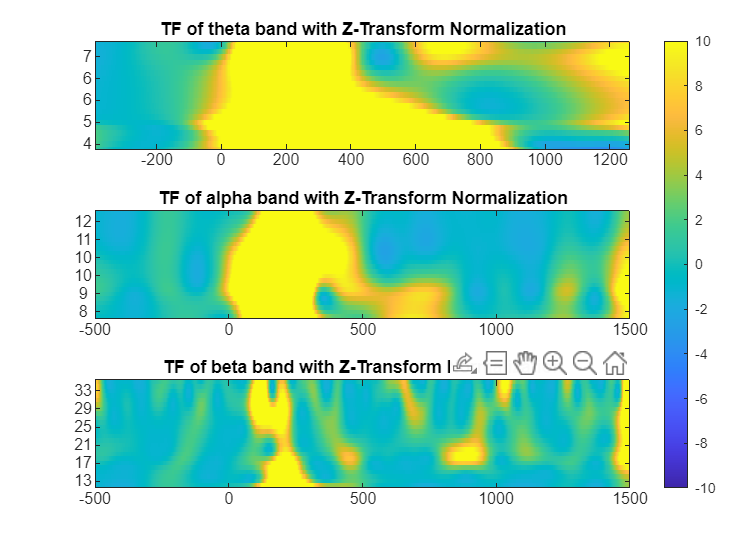

figure;
ytickskip = 2:4:ndiv;
tiledlayout(3,1)
e = 37

%TF plot for theta band with Z-Transform baseline normalization
nexttile()
imagesc(EEG.times,[],ztrans_mean_pow(:,:,1,e))
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band1(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-10 10])
title('TF of theta band with Z-Transform Normalization')

%TF plot for alpha band with Z-Transform baseline normalization
nexttile()
imagesc(EEG.times,[],ztrans_mean_pow(:,:,2,e))
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band2(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-10 10])
title('TF of alpha band with Z-Transform Normalization')

%TF plot for beta band with Z-Transform baseline normalization
nexttile()
imagesc(EEG.times,[],ztrans_mean_pow(:,:,3,e))
set(gca,'ytick',ytickskip,'yticklabel',round(freq_band3(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-10 10])
title('TF of beta band with Z-Transform Normalization')

cb = colorbar();
cb.Layout.Tile = 'east';

###  To create topographical maps of power with and without baseline normalization

load tfdatas.mat

time_index = find(EEG.times >= 200,1);
data2plot = zeros(3, EEG.nbchan, 3);
freq2plot = [find(freq_band1 >= 6,1) find(freq_band2 >= 10,1) find(freq_band3 >= 20,1)];

freq_labels = {'6 Hz (Theta)', '10 Hz (Alpha)', '20 Hz (Beta)'};
norm_labels = {'Raw Power', 'dB Conversion', 'Z-transform'};

for i = 1:3
 data2plot(1,:,i) = tf_mean_pow(freq2plot(i), time_index, i, :);
 data2plot(2,:,i) = tf_dB(freq2plot(i), time_index, i, :);
 data2plot(3,:,i) = ztrans_mean_pow(freq2plot(i), time_index, i, :);
end

figure;
tiledlayout(3,3);
for i = 1:3
    for j = 1:3
        nexttile();
        topoplot(data2plot(j,:,i), EEG.chanlocs, 'electrodes', 'on', 'plotrad', .50);
        cb = colorbar();
        
        title(sprintf('%s\n%s', freq_labels{i}, norm_labels{j}));
    end
end

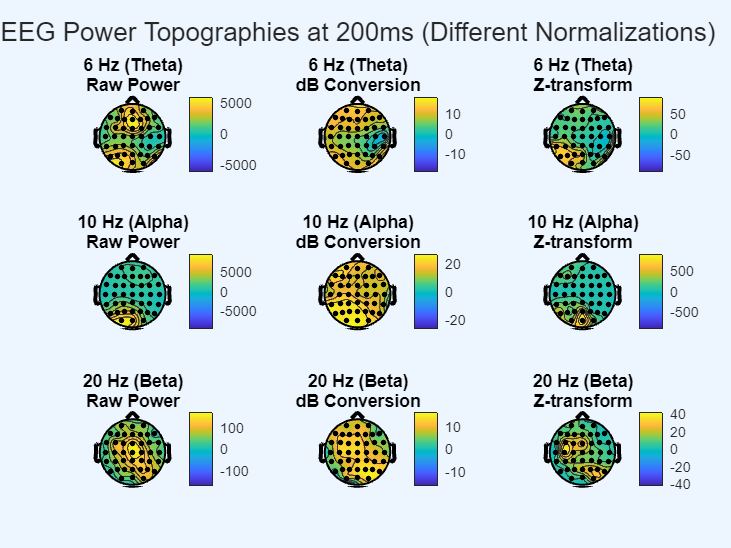

colormap parula

sgtitle('EEG Power Topographies at 200ms (Different Normalizations)');